DSW_st.name='DSW'; 
DSW_st.lat=33.2204;
DSW_st.lon=-108.235;
DSW_st.alt=1775;


DSW_rd=read_betsy('dolly_head',DSW_st.name);

datevec(DSW_rd.Time(1))

ans =         1993           4           2           0           0           0

datevec(DSW_rd.Time(end))

ans =         2007           1           1           0           0           0

prctile(DSW_rd.U_S,[5 50 95])

ans =    39.6800   83.1550   99.5950

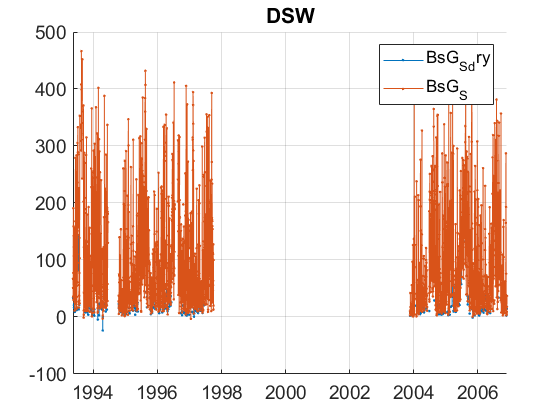

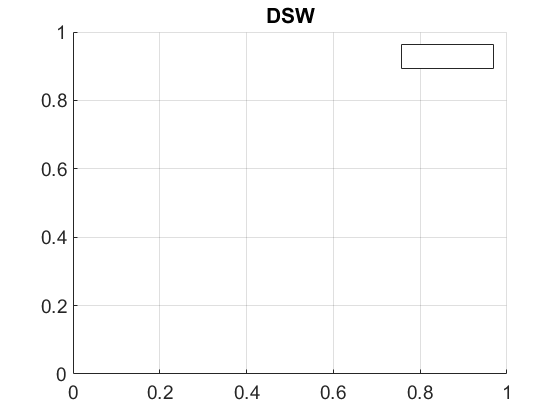

plotFigControl(DSW_rd,DSW_st.name);

% 1 size cut, ok
% sc: ok, max in summer, few negatives



% % lambdaSC=[450;550;700]*ones(1,4);
% % lambdaAE3=[467;530;660]*ones(1,4);
% % lambdaAE7=[370 470 520 590 660 880 950];
% % DSW_cal=compute_exp_SSA(DSW_rd,lambdaSC, lambdaAE);
% % plotFigControl_cal(DSW_cal,DSW_st.name);

%Questions:
%problems:
% holes from July 2011 to April 2012 and from April 2013 to november 2013: real holes of databank problems



DSW_t=timetable(DSW_rd.Time);
% begin at the beginning of a year: 1994
% end: 2006 --> 9y too short